## 平面 $z = \alpha x + \beta y$

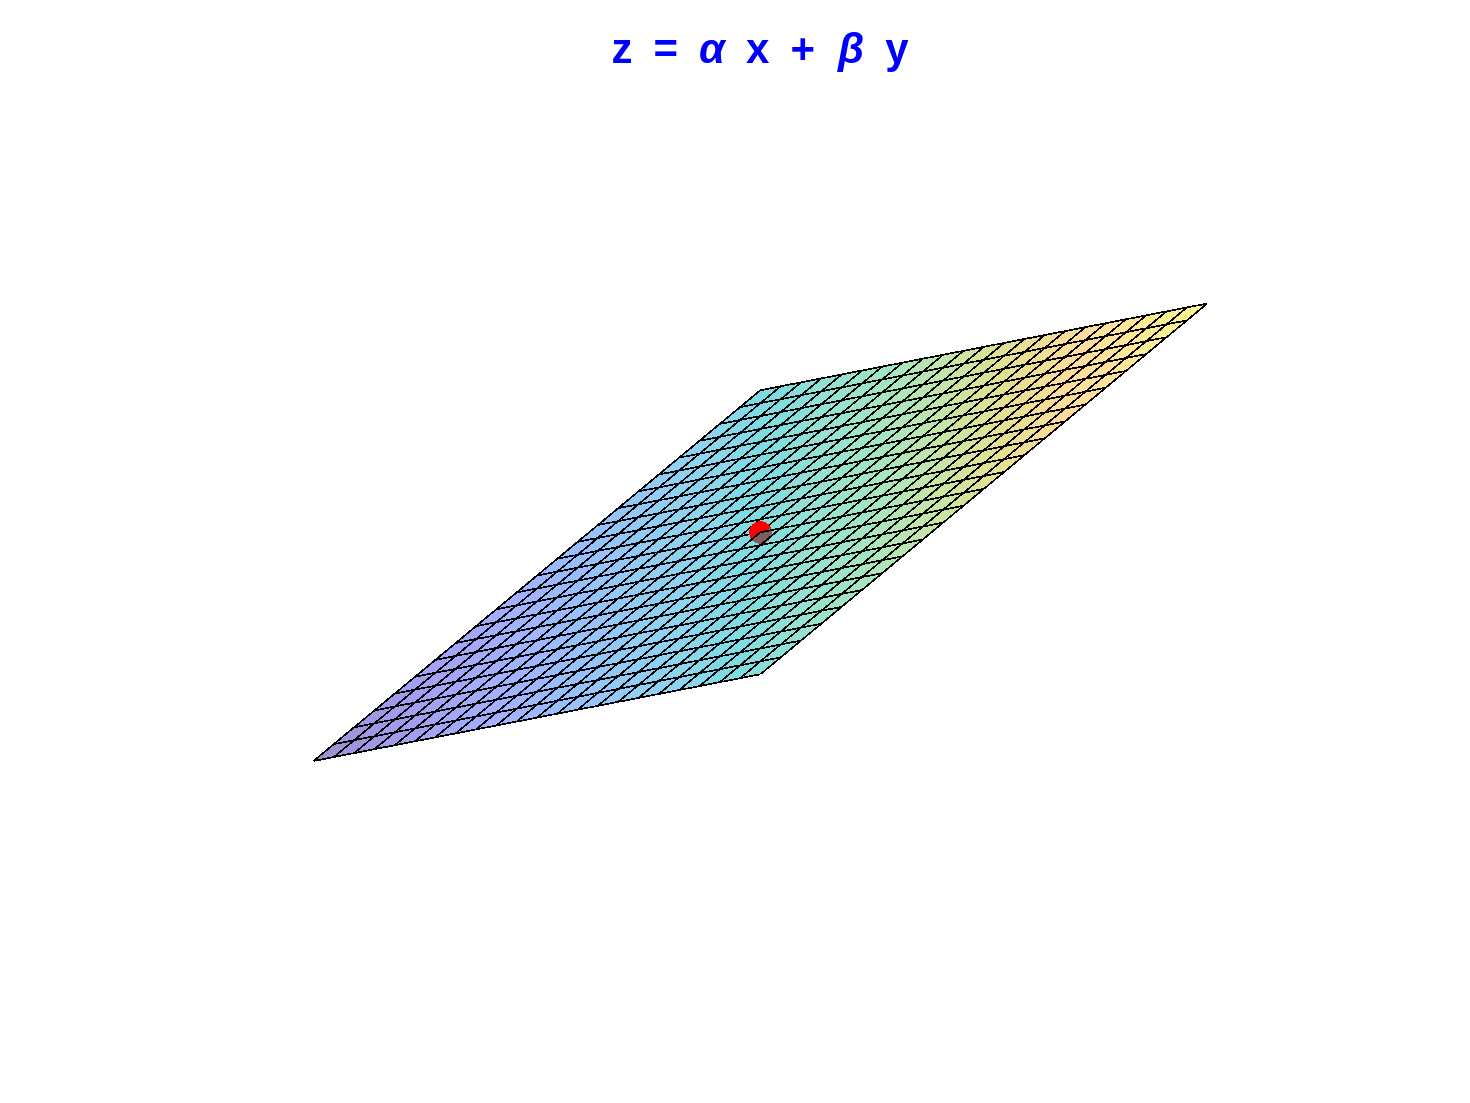

l0=-5.5:0.5:5.5; 
m0=-5.5:0.5:5.5;
[p,q]=meshgrid(l0,m0);
x=p;
y=q;

alpha =1.1;
beta =1;

z=alpha*x + beta*y;

surf(x,y,z,'FaceAlpha',0.5);
axis off
view(45,20)
pbaspect([1 1 1])
title('z = \alpha x + \beta y','Color','blue','FontSize',12)
hold on 
scatter3([0],[0],[0],'filled','MarkerEdgeColor','red','MarkerFaceColor','red');
hold off

## 2変数関数$f(x,y)=-x^2-2y^2$ のグラフと接平面、等高線と勾配ベクトル場

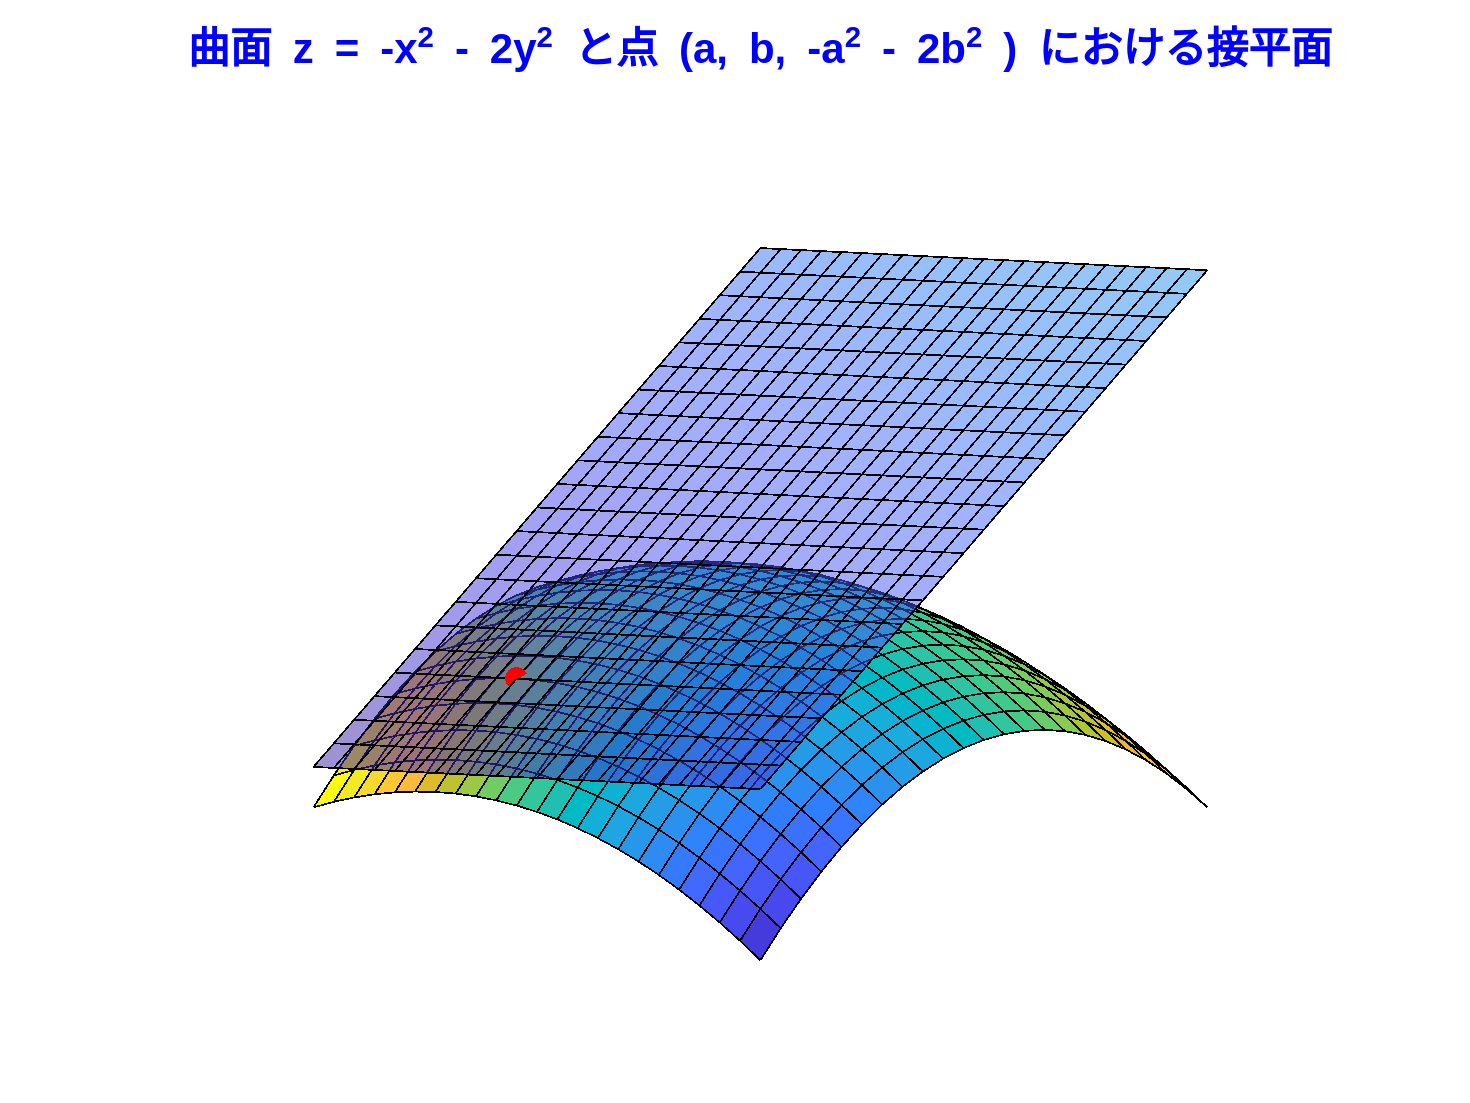

l=-1.1:0.1:1.1; 
m=-1.1:0.1:1.1;
[u,v]=meshgrid(l,m);
x=u;
y=v;
z=-u.^2-2*v.^2;
C1=10*x.*y+10;

a =-0.5;
b =-0.7;

w=a^2+2*b^2-2*a*x-4*b*y;
X=[a];
Y=[b];
Z=[-a^2-2*b^2];

surf(x,y,z,C1);
axis off
xlim([-1.1 1.1])
ylim([-1.1 1.1])
view(45,20)
pbaspect([1 1 1])
title('曲面 z = -x^2 - 2y^2 と点 (a, b, -a^2 - 2b^2 ) における接平面','Color','blue','FontSize',12)
hold on 
surf(x,y,w,'FaceAlpha',0.5);
scatter3(X,Y,Z,'filled','MarkerEdgeColor','red','MarkerFaceColor','red');
hold off

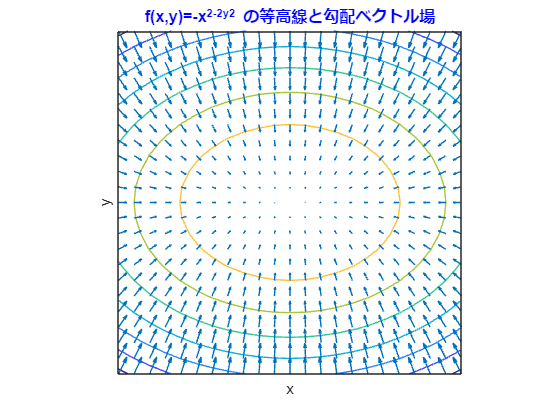

X=-2*x; Y=-4*y;

contour(x,y,z)
title('f(x,y)=-x^2-2y^2 の等高線と勾配ベクトル場','Color','blue','FontSize',12)
xlabel('x')
xticks([])
ylabel('y')
yticks([])
pbaspect([1 1 1])  
hold on
quiver(x,y,X,Y);
hold off